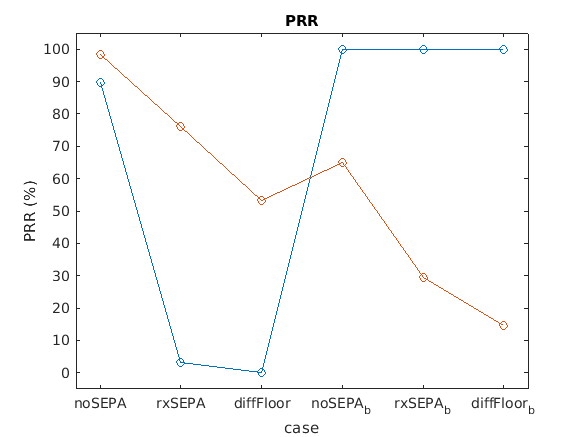

clear;
sentFile = ["1_room_noSEAP_sent.dat"
    "5_room_rxSEAP_sent.dat"
    "9_diffFloor_noSEPA_sent.dat"
    "2_room_noSEAP_sent_b.dat"
    "6_room_rxSEAP_sent_b.dat"
    "10_diffFloor_noSEPA_sent_b.dat"
    ];

sent_cnt = length(sentFile);

recvFile =  ["1_room_noSEAP_recv.dat"
    "5_room_rxSEAP_recv.dat"
    "9_diffFloor_noSEPA_recv.dat"
    "2_room_noSEAP_recv_b.dat"   
    "6_room_rxSEAP_recv_b.dat"
    "10_diffFloor_noSEPA_recv_b.dat"
    ];
    
recv_cnt = length(recvFile);

mean_nretx = [];
mean_result = [];
mean_delay = [];
mean_diversity = [];
mean_snr= [] ;
mean_rssi = [];

mean_recv_len = [];
for cnt = 1:1:sent_cnt
    
    sent_array= csvread(sentFile(cnt));
    recv_array = csvread(recvFile(cnt));
    
    
    mean_nretx = [mean_nretx mean(sent_array(:,2))];
    mean_result = [mean_result mean(sent_array(:,3))];
    mean_delay = [mean_delay mean(sent_array(:,4))];
    
    mean_diversity = [mean_diversity mean(recv_array(:,2))];
    mean_snr = [mean_snr mean(recv_array(:,3))];
    mean_rssi = [mean_rssi mean(recv_array(:,4))];
    
    mean_recv_len = [mean_recv_len length(recv_array')];
end

plot([[mean_result * 100 ; mean_recv_len * 0.1]'],'-o');
xlim([0.7 6.3])
ylim([-5 105])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("PRR (%)")
title("PRR");

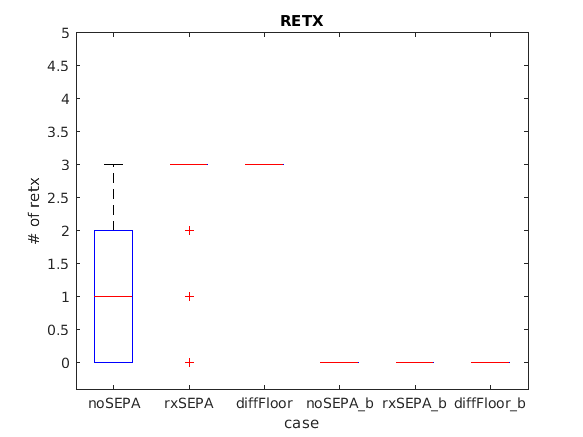





for cnt = 1:1:sent_cnt
    csvread(recvFile(cnt));
    sent_data(cnt)= {csvread(sentFile(cnt))};
    recv_data(cnt) = {csvread(recvFile(cnt))};
end

sent_array = cell2mat(sent_data);

recv_array = [];
for cnt = 1:1:recv_cnt
    temp_data =cell2mat(recv_data(cnt));
    while length(temp_data) < 950
        temp_data = [temp_data ;temp_data];
    end
    temp_data = temp_data(1:950,:);
    recv_array = [recv_array temp_data];
end


nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

for cnt = 1:1:sent_cnt
    nretx = [nretx sent_array(:,2 + 4*(cnt-1))];
    result = [result sent_array(:,3 + 4*(cnt-1))];
    delay = [delay sent_array(:,4*cnt)];
    
    diversity = [diversity recv_array(:,2 + 4*(cnt -1))];
    snr = [snr recv_array(:,3 + 4*(cnt -1))];
    rssi = [rssi recv_array(:,4*cnt)];
end

result_mean = [];
for cnt = 1:1:sent_cnt
    result_mean = [result_mean mean(result(:,cnt))];
end

boxplot(nretx);
title("nretx");
ylim([-0.4 5])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("# of retx")
title("RETX");

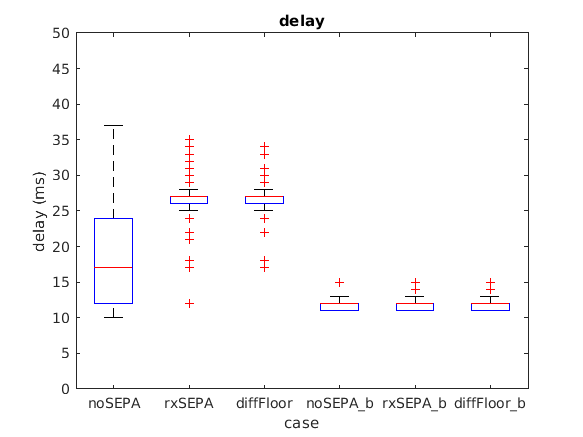




boxplot(delay);
title("delay");
ylim([0 50])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("delay (ms)")

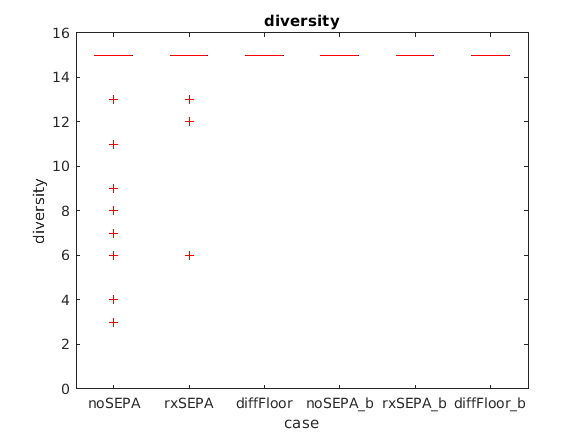



boxplot(diversity);
title("diversity");
ylim([0 16])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("diversity")

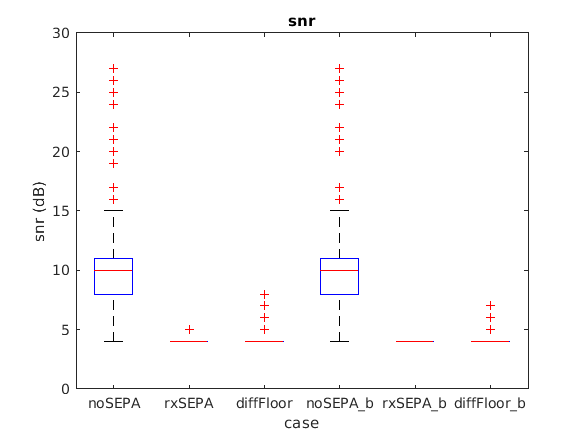



boxplot(snr);
title("snr");
ylim([0 30])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("snr (dB)")

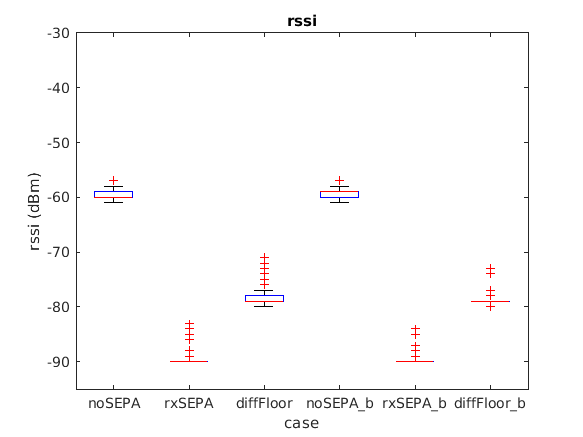




boxplot(rssi);
title("rssi");
ylim([-95 -30])
xticks([1,2,3,4,5,6])
xticklabels({'noSEPA','rxSEPA','diffFloor','noSEPA_b','rxSEPA_b','diffFloor_b'})
xlabel("case")
ylabel("rssi (dBm)")